# NucleoidOccupancyAnalysis.mlx 

% ===================================================================

%  Copyright © 2023-2025 Xiaofeng Dai (xiaofend@umich.edu)

%  SPDX-License-Identifier: GPL-3.0-or-later

%

%  This program is free software: you can redistribute it and/or modify

%  it under the terms of the GNU General Public License as published by

%  the Free Software Foundation, either version 3 of the License, or

%  (at your option) any later version.

%

%  This program is distributed in the hope that it will be useful,

%  but WITHOUT ANY WARRANTY; without even the implied warranty of

%  MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the

%  GNU General Public License for more details.

%

%  You should have received a copy of the GNU General Public License

%  along with this program (LICENSE file in the repository root).

%  If not, see <https://www.gnu.org/licenses/>.

%

%  Tested with: MATLAB R2024a and R2022a

% ===================================================================

### NUCLEOID OCCUPANCY ANALYSIS (LIVE SCRIPT)

% ---------------------------------------------------------------

% This live script:

%   • Loads cell masks and fluorescence image stacks (ND2) for multiple movies/fields.

%   • Converts ND2 to `.mat` where necessary (via `Movie2mat`, from 'SMALL-LABS' the %      tracking algorithm we used ) and sums frames to obtain final staining intensities.

%   • Detects nucleoid regions inside each segmented cell by adaptive

%     two‑step background subtraction using Gaussian‑mixture modelling

%     (helper `GetNucleoid`).

%   • Measures geometry (Feret diameters) and intensity statistics for

%     entire cells vs. nucleoid mask; stores per‑cell metrics.

%   • Performs DBSCAN clustering on super‑threshold nucleoid pixels to

%     estimate the number of dense sub‑domains.

%   • Applies multi‑criteria filtering (cell length, intensity variance,

%     mean intensity, cluster count) to select high‑quality cells.

%   • Outputs histograms of nucleoid occupancy, and

%     includes an interactive sanity‑check block for manual inspection.

% -------------------------------------------------------------------------

### Load data and get cell mak & staining intensity 

Folder = uigetdir('Example_Folder/subfolder');
maskname = uigetfile([Folder,filesep,'*PhaseMask.tif'],'MultiSelect',"on");
stainname = uigetfile([Folder,filesep,'*.nd2'],'MultiSelect',"on");
Num_mov = length(maskname);
Store_mask = cell(Num_mov,1);
Store_stain = cell(Num_mov,1);
parfor i = 1:Num_mov
    filepath = strcat(Folder,filesep,maskname{i});
    Store_mask{i} = imread(filepath);
end
clear filepath i

parfor i = 1:Num_mov
    filepath = strcat(Folder,filesep,stainname{i});
    try 
        mov = load([filepath(1:end-3),'mat']);
        mov = mov.mov;
        mov = sum(mov,3);
    catch
        Movie2mat(filepath);
        filepath = [filepath(1:end-3),'mat'];
        mov = load(filepath);
        mov = mov.mov;
        mov = sum(mov,3);
    end
    Store_stain{i} = mov;
end
clear i filepath mov Num_mov
clearvars -except Folder Store_stain Store_mask maskname stainname

### Nucleoid region detection 

% adjust to iterate subset of movies
mov_start = 1;
mov_end = 30;

Store_result = cell(mov_end-mov_start+1,1);
parfor i = mov_start:mov_end
    mask = Store_mask{i};
    mov = Store_stain{i};
    num_cell = max(max(mask));
    % store result for each cell
    % col1-cell index, mov_index*1000+cell_index
    % col2-size of cell, clo3-length of cell, col4-width of cell
    % col5-size of nuc, col6-length of nuc, col7-width of nuc
    % col8-threshold of nuc detection, 
    % col9-var of intensity/ col9-10% max intensity - 10% min intensity
    % col10-avg intensity of the cell
    single_result = zeros(num_cell,10);
    roi_size=size(mask);
    for j = 1:num_cell
        single_result(j,1) = j+i*1000;
        submask = mask;
        submask(mask~=j) = 0;
        submov = mov;
        submov(mask~=j) = 0;
        
        [ind1, ind2]=find(submask==j);
        if isempty(ind1)
            continue
        end
        r_up=min(ind1);
        r_up=max(1,r_up-10);
        r_down=max(ind1);
        r_down=min(r_down+10,roi_size(1));
        col_left=min(ind2);
        col_left=max(1,col_left-10);
        col_right=max(ind2);
        col_right=min(roi_size(2),col_right+10);
        
        submask = submask(r_up:r_down,col_left:col_right);
        submask = submask/j;
        submov = submov(r_up:r_down,col_left:col_right);
        try
            [Nuc, thres] = GetNucleoid(submask, submov, 1, 1.5, 'off');
            Nuc(Nuc~=0) = 1;
            Nuc = imfill(Nuc,"holes");
            
            Area_cell = length(find(submov~=0));
            Area_nuc = length(find(Nuc~=0));
            
            ImgProp = regionprops('table',submask,'PixelList');
            FeretAna = feretProperties(ImgProp);
            cell_length=FeretAna.MaxFeretDiameter;
            cell_width=FeretAna.MinFeretDiameter;
            
            ImgProp = regionprops('table',Nuc,'PixelList');
            FeretAna = feretProperties(ImgProp);
            Nuc_length=FeretAna.MaxFeretDiameter;
            Nuc_width=FeretAna.MinFeretDiameter;
            
            single_result(j,2) = Area_cell;
            single_result(j,3) = cell_length;
            single_result(j,4) = cell_width;
            single_result(j,5) = Area_nuc;
            single_result(j,6) = Nuc_length;
            single_result(j,7) = Nuc_width;
            
            single_result(j,8) = thres;
            
%             % use difference of 10% of max and min
%             buff = submov(submov~=0);
%             max_int = maxk(buff,floor(0.05*length(buff)));
%             min_int = mink(buff,floor(0.05*length(buff)));
%             single_result(j,9) = mean(max_int)-mean(min_int);
            
            % use variance of normalized intensity 
            buff = submov(submov~=0);
            single_result(j,10) = sum(buff)/length(buff);
            buff = (buff-min(buff))/(max(buff)-min(buff));
            single_result(j,9) = var(buff);
            
            
            
        catch
            mov_ind = num2str(i);
            cell_ind = num2str(j);
            str = strcat('error in mov #',mov_ind,', cell #',cell_ind);
            disp(str)
        end
        
    end
    Store_result{i} = single_result;
end

error in mov #15, cell #3
error in mov #10, cell #1



clear i mask mov num_cell single_result roi_size
clear j submask submov ind1 ind2 r_up r_down col_left col_right
clear Nuc thres Area_nuc Area_cell ImgProp FeretAna
clear cell_width cell_length Nuc_length Nuc_width 
clear buff max_int min_int
clear cell_ind mov_ind str

### Global histograms for filtering

disp('filter plot')

filter plot


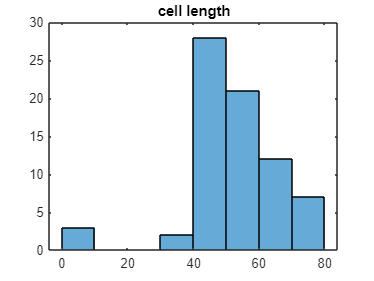

Result = cat(1,Store_result{:});
% cell length
figure
histogram(Result(:,3))
title('cell length')

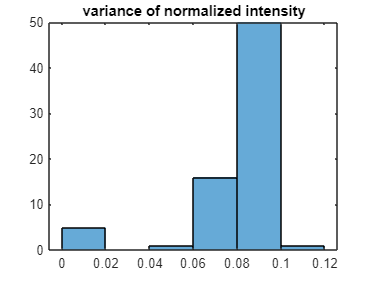

% intensity variance
figure
histogram(Result(:,9))
title('variance of normalized intensity')

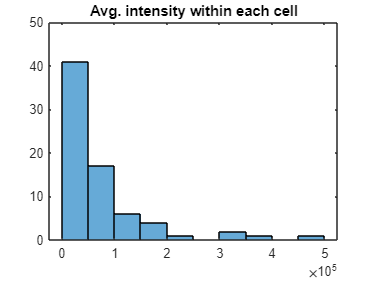

% average intensity
figure
histogram(Result(:,10))
title('Avg. intensity within each cell')

disp('-------------------------------------------------------------')

-------------------------------------------------------------



% Cluster analysis for nucloid region (# of clusters)
Store_clus = cell(length(Store_result),1);
for i = 1:length(Store_result)          
    mask = Store_mask{i};
    mov = Store_stain{i};
    res = Store_result{i};
    buff = cell(height(res),1);
    for j = 1:height(res)               
        thres = res(j,8);
        if thres~=0
            submask = mask;
            submask(mask~=j) = 0;
            submov = mov;
            submov(mask~=j) = 0;
            
            roi_size=size(mask);
            [ind1, ind2]=find(submask==j);
            r_up=min(ind1);
            r_up=max(1,r_up-10);
            r_down=max(ind1);
            r_down=min(r_down+10,roi_size(1));
            col_left=min(ind2);
            col_left=max(1,col_left-10);
            col_right=max(ind2);
            col_right=min(roi_size(2),col_right+10);
            
            submask = submask(r_up:r_down,col_left:col_right);
            submask = submask/j;
            submov = submov(r_up:r_down,col_left:col_right);
            
            Mask_load = submask;
            Staining_load = submov;
            Staining_load(Mask_load==0)=0;
        
            Intensity_2D=Staining_load;
            Intensity_2D(Staining_load<=thres)=0;
            
            [coordx, coordy]=find(Intensity_2D~=0);
            coord = [coordx coordy];
            clear coordx coordy
            coord_clus = dbscan(coord,2,8);
            buff{j} = coord_clus;
%             figure
%             gscatter(coord(:,1),coord(:,2),coord_clus)
        else
            buff{j} = [];
        end
    end
    Store_clus{i} = buff;
end

clear i j mask mov res thres str_tl submask submov roi_size ind1 ind2
clear r_up r_down col_left col_right Mask_load Staining_load Intensity_2D Bndry
clear buff coord coord_clus

filter_clus = cell(length(Store_clus),1);
for i = 1:length(Store_result)
    clus_per_mov = Store_clus{i};
    buff = zeros(length(clus_per_mov),1);
    for j = 1:length(clus_per_mov)
        clus_cell = clus_per_mov{j};
        if ~isempty(clus_cell)
            ind_clus = unique(clus_cell);
            ind_clus(ind_clus<0)=[];
            num_clus = 0;
            if ~isempty(ind_clus)
                for k = 1:length(ind_clus)
                    ind = ind_clus(k);
                    num_pix = length(find(clus_cell==ind));
                    if num_pix>25
                        num_clus = num_clus+1;
                    end
                end
            end
        else
            num_clus = -1;
        end
        buff(j) = num_clus;
    end
    filter_clus{i} = buff;
end
clear i clus_per_mov buff j clus_cell ind_clus num_clus k ind num_pix
Num_clus = filter_clus;
filter_clus = cat(1,filter_clus{:});

### Build filter based on geometry & intensity criteria

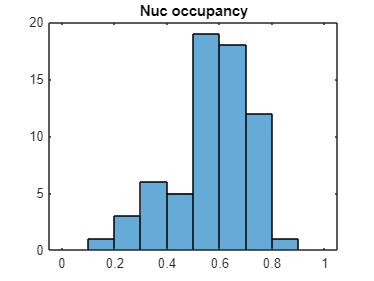

filter_result = zeros(height(Result),4); 
% cell length
filter_cellen = [35 95];
filter_result(Result(:,3)>=filter_cellen(1) & Result(:,3)<=filter_cellen(2),1) = 1;
% intensity variance
filter_intvar = [0.02 0.10];
filter_result(Result(:,9)>=filter_intvar(1) & Result(:,9)<=filter_intvar(2),2) = 1;
% average intensity
filter_intavg = [2e4 1e6];
filter_result(Result(:,10)>=filter_intavg(1) & Result(:,10)<=filter_intavg(2),3) = 1;
% # of clusters
clus_num = [1,3];
filter_result(filter_clus>=clus_num(1) & filter_clus<=clus_num(2),4) = 1;

Result_filtered = Result;
Result_filtered(sum(filter_result,2)~=4,:)=[];

clear filter_result filter_clus

figure
histogram(Result_filtered(:,5)./Result_filtered(:,2),(0:0.1:1))
title('Nuc occupancy')

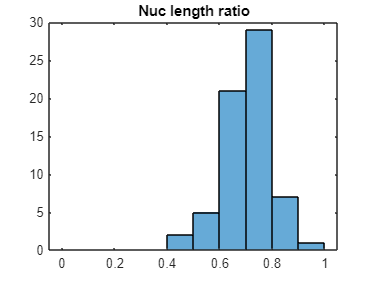

figure
histogram(Result_filtered(:,6)./Result_filtered(:,3),(0:0.1:1))
title('Nuc length ratio')

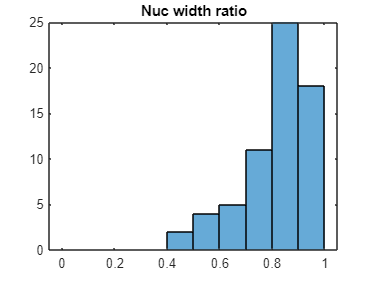

figure
histogram(Result_filtered(:,7)./Result_filtered(:,4),(0:0.1:1))
title('Nuc width ratio')


% Result_filtered(Result_filtered(:,7)./Result_filtered(:,4)>0.99,:)
Ratio_result = zeros(height(Result_filtered),3);
Ratio_result(:,1) = Result_filtered(:,5)./Result_filtered(:,2); % Nuc occupancy
Ratio_result(:,2) = Result_filtered(:,6)./Result_filtered(:,3); % Nuc length ratio
Ratio_result(:,3) = Result_filtered(:,7)./Result_filtered(:,4); % Nuc width ratio

## Sanity Check

change 'i' value to iterate through movies

Deter = cell(length(Store_mask),1);
for i = 1:length(Deter)
    clus = Num_clus{i};
    res = Store_result{i};
    buff = zeros(length(clus),4);
    buff(res(:,3)>=filter_cellen(1) & res(:,3)<=filter_cellen(2),1) = 1;
    buff(res(:,9)>=filter_intvar(1) & res(:,9)<=filter_intvar(2),2) = 1;
    buff(res(:,10)>=filter_intavg(1) & res(:,10)<=filter_intavg(2),3) = 1;
    buff(clus>=clus_num(1) & clus<=clus_num(2),4) = 1;
    Deter{i} = sum(buff,2);
end
clear filter_cellen filter_intvar filter_intavg clus_num
clear i clus res buff

mov#2__cell#2


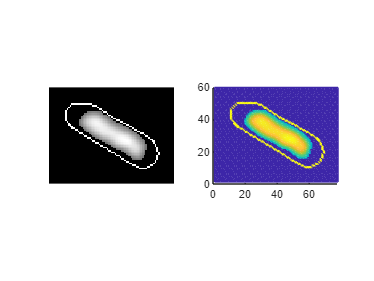

for i = 2         %length(Store_Mask)
    mask = Store_mask{i};
    mov = Store_stain{i};
    res = Store_result{i};
    deter = Deter{i};
    for j = 1:height(res)               
        thres = res(j,8);
        if thres~=0 && deter(j)==4
            str_tl = strcat('mov#',num2str(i),'__','cell#',num2str(j));
            disp(str_tl)
            submask = mask;
            submask(mask~=j) = 0;
            submov = mov;
            submov(mask~=j) = 0;
            
            roi_size=size(mask);
            [ind1, ind2]=find(submask==j);
            r_up=min(ind1);
            r_up=max(1,r_up-10);
            r_down=max(ind1);
            r_down=min(r_down+10,roi_size(1));
            col_left=min(ind2);
            col_left=max(1,col_left-10);
            col_right=max(ind2);
            col_right=min(roi_size(2),col_right+10);
            
            submask = submask(r_up:r_down,col_left:col_right);
            submask = submask/j;
            submov = submov(r_up:r_down,col_left:col_right);
            
            Mask_load = submask;
            Staining_load = submov;
            Staining_load(Mask_load==0)=0;
        
            Intensity_2D=Staining_load;
            Intensity_2D(Staining_load<=thres)=0;
            Intensity_2D=imfill(Intensity_2D,"holes");
            Bndry=edge(Mask_load);
            Intensity_2D(Bndry==1) = max(Intensity_2D,[],'all');
            
            figure
            subplot(1,2,1)
            imshow(Intensity_2D,[])
            subplot(1,2,2)
            mesh(flipud(Intensity_2D))
            view([0 90])
            xlim([0, 0+width(Intensity_2D)])
            ylim([0, 0+height(Intensity_2D)])
            pbaspect([width(Intensity_2D)/height(Intensity_2D) 1 1])
        end
    end
end

clear i j mask mov res thres str_tl submask submov roi_size ind1 ind2 deter Deter
clear r_up r_down col_left col_right Mask_load Staining_load Intensity_2D Bndry

### **Helper Functions**

---------------------------------------------------------------------------

GetNucleoid(mask, staining, bd_sig1, bd_sig2, figplot)

% Two-step adaptive background subtraction based on Gaussian mixture

% fitting of intensity distributions at successive mask boundaries.

% Returns a binary nucleoid mask (Intensity_2D) and the final threshold

Gauss2Peak(xdata,ydata)

% Non-linear least-squares fitting of a two-component Gaussian model

% to 1-D histogram data.

---------------------------------------------------------------------------

function [Intensity_2D,threshold]=GetNucleoid(mask, staining, bd_sig1, bd_sig2, figplot)
    staining(mask==0)=0;
    Bndry=edge(mask);
    Mask_peel1=mask;
    Mask_peel1(Bndry==1)=0;
    Bndry_layer2=edge(Mask_peel1);
    Bg=staining(Bndry_layer2==1);
    Bg(Bg==0)=[];
%     Bg_intensity=sum(Bg)/length(Bg);
    
    Num_bin=20;
    [ydata, buff]=histcounts(Bg,Num_bin,'Normalization',"probability");  
    ydata=ydata.';
    xdata=zeros(Num_bin,1);
    for i=1:Num_bin
        xdata(i)=(buff(i)+buff(i+1))/2;
    end
    clear i buff
    para=Gauss2Peak(xdata,ydata); %% use 2 peak gaussian fitting
%     para=Better_fit(xdata,ydata); %% 1/2 peaks based on error
%     Thres1=para(2)+bd_sig1*para(3);  %% use 1st peak
    Thres1=para(5)-bd_sig1*para(6);  %% use 2nd peak - a*std
    Intensity_2D=staining;
    Intensity_2D(staining<=Thres1)=0;
    
    
    Bndry2nd=edge(Intensity_2D);
    Bg2=staining(Bndry2nd==1);
    Bg2(Bg2==0)=[];
%     Bg_intensity=sum(Bg2)/length(Bg2);
    
    Num_bin=20;
    [ydata, buff]=histcounts(Bg2,Num_bin,'Normalization',"probability");    
    ydata=ydata.';
    xdata=zeros(Num_bin,1);
    for i=1:Num_bin
        xdata(i)=(buff(i)+buff(i+1))/2;
    end
    clear i buff
    para2=Gauss2Peak(xdata,ydata); %% use 2 peaks gaussian fitting
%     para2=Better_fit(xdata,ydata); %% choose 1/2 peaks based on error
    clear xdata ydata

%     Thres2=para2(2)+bd_sig2*para2(3);  %% use 1st peak
    Thres2=para2(5)+bd_sig2*para2(6);  %% use 2nd peak + a*std
    threshold=Thres2;
    
    Intensity_2D=staining;
    Intensity_2D(staining<=Thres2)=0;
    switch figplot
        case 'on'
            [lena, lenb]=size(staining);
            figure
            subplot(1,2,1)
            mesh(staining)
            view([0 90])
            title('Intensity')
            axis equal
            ylim([0, lena])
            xlim([0, lenb])
            subplot(1,2,2)
            mesh(Intensity_2D)
            view([0 90])
            title('Intensity after 2nd BG substraction')
            axis equal
            ylim([0, lena])
            xlim([0, lenb])
        otherwise
    end
%     a=length(mask(mask~=0));
%     b=length(Intensity_2D(Intensity_2D~=0));
%     Nucleoid_Occupancy = b/a;
    
end

function p_fit=Gauss2Peak(xdata,ydata)
    fun = @(p,xdata)  p(1)*exp(-((xdata-p(2))/p(3)).^2) + p(4)*exp(-((xdata-p(5))/p(6)).^2)+p(7);
    p_initial = [0.1,(max(xdata)-min(xdata))/4+min(xdata),max(xdata)/20,0.1,3*(max(xdata)-min(xdata))/4+min(xdata),max(xdata)/10,min(ydata)/20];
    lb = [0,min(xdata),0,0,min(xdata),0,0];
    ub = [1,max(xdata),max(xdata),1,max(xdata),max(xdata),max(ydata)];
    % x(1) height of peak1; x(2) center_1; x(3) sigma_1; x(4) height of peak 2; x(5) center_2; x(6) sigma_2; x(7) error 
    opt=optimset('Display','off');
    p_fit = lsqcurvefit(fun,p_initial,xdata,ydata,lb,ub,opt);
end


%% Based on weight instead of intensity
% function p_fit = Better_fit(xdata,ydata)
%     [peak2_fit, ~] = Gauss2Peak(xdata, ydata);
%     pop1 = peak2_fit(1);
%     pop2 = peak2_fit(4);
%     if pop2/pop1>=1
%         p_fit = peak2_fit(4:6);
%     else
%         p_fit = peak2_fit(1:3);
%     end
% end
